### Experiments on Outlying Function:

clear % Add repository folders to path
mfilePath = mfilename('fullpath');
if contains(mfilePath,'LiveEditorEvaluationHelper')
    mfilePath = matlab.desktop.editor.getActiveFilename;
end
folder_path = strsplit(mfilePath,filesep);
repo_path = join([folder_path(1:end-2)],filesep);
repo_path = repo_path{1};
data_path = [repo_path,filesep,'data'];
src_path = [repo_path,filesep,'src'];
tenandet_path = [repo_path,filesep,'tenandet'];
testbench_path = [repo_path,filesep,'testbench'];
addpath(genpath(data_path), genpath(src_path),genpath(tenandet_path), genpath(testbench_path));
clear folder_path mfilePath repo_path data_path testbench_path src_path tenandet_path

### Load NYC data

sizes = [144,7,52,10];                                      % Load NYC data 
load nyc_tensors.mat
load regions.mat
arrs = squeeze(sum(reshape(arrs,6,24,365,[]),1)); 
Y = double(reshape(arrs(:,1:364,regions), 24, 7, 52,[]));   % Select 81 zones
Y(:,1,53,:) = arrs(:,365,regions);
Y(:,2:7,53,:) = mean(Y(:,2:7,1:52,:),3);                 % Fill in the last week with the mean of other weeks

**EXP1: Anomaly Amplitude vs AUC**

Number of anomalous locations = 5

cs = [2,3,4,5,6];
NoAD = 5;
NoA = 100*NoAD;
LoA =8;
sz = size(Y);
NoT = 3;
outlying_scores = zeros(81,length(cs),NoT);
auc = zeros(length(cs),NoT);

tstart = tic

tstart = uint64
6861420737342

parfor i =1:length(cs)
    for t=1:NoT
        select_loc = randperm(81,NoAD);
        Anomaly_mask = zeros(sz);
        a = zeros([sz(1:3),5]);
        [a, anomaly_mask] = add_persistent_anomaly(Y(:,:,:,select_loc),LoA,NoA,cs(i),1);
        Yn = Y;
        Yn(:,:,:,select_loc) = Y(:,:,:,select_loc) + a;
        Anomaly_mask(:,:,:,select_loc) = anomaly_mask;
        
        Sn = cell(81,1);
        outlying_score = zeros(81,1);
        for n =1:81
            Sn{n}= squeeze(Yn(:,:,:,n));
        end

        for n=1:81
            z = Sn{n};
            %outlying_score(n) 
            [OS, Or]= outlying_function2(z,Sn,30,1e-3,0);
            outlying_score(n)= OS;
            if mod(n,10)==0
                disp(n)%outlying_score(n)
            end
        end
        outlying_scores(:,i,t)= outlying_score;
        labels= {'Normal'};
        labels =repmat(labels,81,1);
        for k=select_loc
            labels{k} = 'Anomaly'; 
        end
        classNames = cell(2,1);
        classNames{1}='Normal';
        classNames{2}='Anomaly';
        score = [-outlying_scores(:,i,t),outlying_scores(:,i,t)];
        try
            rocObj = rocmetrics(labels,score,classNames);
            auc(i,t) = rocObj.AUC(1);
        catch ME
            disp('Sacma sapan bisi')
        end
    end
end


n =

    10


n =

    20


n =

    30


n =

    40


n =

    50


n =

    60


n =

    70


n =

    80


n =

    10


n =

    20


n =

    30


n =

    40


n =

    50


n =

    60


n =

    70


n =

    80


n =

    10


n =

    20


n =

    30


n =

    40


n =

    50


n =

    60


n =

    70


n =

    80


n =

    10


n =

    20


n =

    30


n =

    40


n =

    50


n =

    60


n =

    70


n =

    80


n =

    10


n =

    20


n =

    30


n =

    40


n =

    50


n =

    60


n =

    70


n =

    80


n =

    10


n =

    20


n =

    30


n =

    40


n =

    50


n =

    60


n =

    70


n =

    80


n =

    10


n =

    20


n =

    30


n =

    40


n =

    50


n =

    60


n =

    70


n =

    80


n =

    10


n =

    20


n =

    30


n =

    40


n =

    50


n =

    60


n =

    70


n =

    80


n =

    10


n =

    20


n =

    30


n =

    40


n =

    50


n =

    60


n =

    70


n =



tEnd = toc(tstart)

tEnd = 430.9127

results.auc = auc;
results.cs = cs;
results.NoAD = 5;
results.NoA = 100*NoAD;
results.LoA =8;
results.NoT = 1;
results.time_spent = tEnd;
save('exp1_amplitude_vs_auc_ez2.mat','results');

**Plot Exp1 Results: Anomaly amplitude vs AUC**

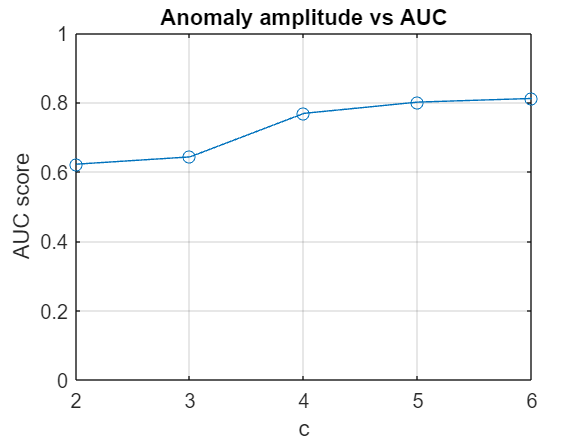

expf = figure;
plot(results.cs,mean(results.auc,2),'o-')
grid on
xlabel('c')
ylabel('AUC score')
ylim([0,1]);
title('Anomaly amplitude vs AUC')

## Exp 2: Number of anomalous locations vs AUC

cs = 4;
NoAL = [1,2,4,8,16,32];
NoA = 100*NoAL;
LoA =8;
sz = size(Y);
NoT = 10;
outlying_scores = zeros(81,length(NoAL),NoT);
auc = zeros(length(NoAL),NoT);

parfor i =1:length(NoAL)
    for t=1:NoT
        select_loc = randperm(81,NoAL(i));
        Anomaly_mask = zeros(sz);
        a = zeros([sz(1:3),5]);
        [a, anomaly_mask] = add_persistent_anomaly(Y(:,:,:,select_loc),LoA,NoA(i),cs,1);
        Yn = Y;
        Yn(:,:,:,select_loc) = Y(:,:,:,select_loc) + a;
        Anomaly_mask(:,:,:,select_loc) = anomaly_mask;
        
        Sn = cell(81,1);
        outlying_score = zeros(81,1);
        for n =1:81
            Sn{n}= squeeze(Yn(:,:,:,n));
        end

        for n=1:81
            z = Sn{n};
            % outlying_score(n) 
            [OS, Or]= outlying_function2(z,Sn,60,1e-4,1);
            outlying_score(n)= OS;
            if mod(n,18)==0
                disp(n)
            end
        end
        outlying_scores(:,i,t)= outlying_score;
        labels= {'Normal'};
        labels =repmat(labels,81,1);
        for k=select_loc
            labels{k} = 'Anomaly'; 
        end
        classNames = cell(2,1);
        classNames{1}='Normal';
        classNames{2}='Anomaly';
        score = [-outlying_scores(:,i,t),outlying_scores(:,i,t)];
        try
            rocObj = rocmetrics(labels,score,classNames);
            auc(i,t) = rocObj.AUC(1);
        catch ME
            disp('Sacma sapan bisi')
        end
    end
end
auc(auc==0)=NaN
tEnd = toc(tstart);
results.auc = auc;
results.cs = 4;
results.NoAL = NoAL;
results.NoA = NoA;
results.LoA = LoA;
results.NoT = NoT;
results.time_spent = tEnd;
save('exp2_NumofA_vs_auc_ez.mat','results');

**Exp 2: Number of anomalous locations vs AUC**

**24x7x53x81**

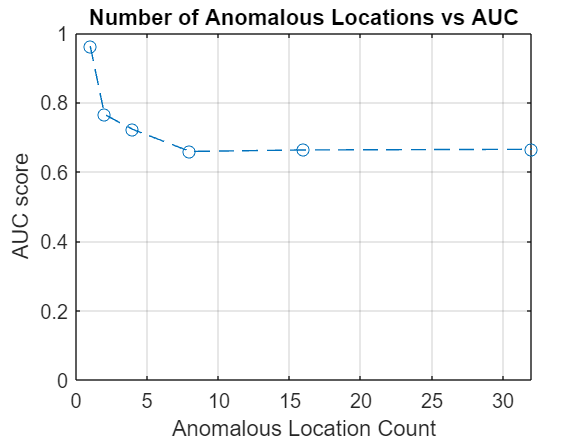

expf2 = figure;
plot(results.NoAL,mean(auc,2,'omitnan'),'o--')
grid on
xlabel('Anomalous Location Count')
ylabel('AUC score')
ylim([0,1]);
title('Number of Anomalous Locations vs AUC')


window_length=500;
day_count = floor(window_length/24);
figure;
yn = t2m(Yn,4);
y = t2m(Y,4);
t = [1:window_length]; days = [1:day_count]*24;
plot(t,yn(select_loc(5),1:window_length),'k')
hold on;
plot(t,y(select_loc(5),1:window_length),'r')
xlabel("Time (hrs)")
xline(days,'--b')

**Run LOSS function with parameters:**

param = set_params(Yn);
% param.beta_1=1;
% param.beta_2=1;
% param.beta_3=1;
% param.beta_4=1;
% param.beta_5=1;
param.lambda=1e-1;
param.gamma=1e-1;
% param.alpha=0;
param.err_tol=1e-4;
param.max_iter=400;
tic
[L,S,~,~]= loss(Yn, param);
toc
locations = select_loc;
window_length=500;
day_count = floor(window_length/24);
t = [1:window_length]; days = [1:day_count]*24;
s= t2m(S,4);
l= t2m(L,4);

f1=figure;
clear f1
f1 = figure;
plot(t,yn(locations(1),1:window_length),'black')
hold on
plot(t,y(locations(1),1:window_length),':black')
plot(t,l(locations(1),1:window_length),'--blue')
plot(t,s(locations(1),1:window_length),'red')
xlabel("Time (hrs)")
xline(days,'--g')
legend('Anomalous', 'Real', 'L','S','Days');

## Calculate outlying scores

Sn = cell(81,1);
outlying_score = zeros(81,1);
for n =1:81
    Sn{n}= squeeze(S(:,:,:,n));
end
tic
for n=1:81
    z = Sn{n};
    % outlying_score(n) 
    [OS, Or]= outlying_function2(z,Sn,150,1e-3,1);
    outlying_score(n)= OS;
    if mod(n,18)==0
        n
    end
end
toc

figure
plot(Or)